clear; close all;

Treatment = "ChemoBiM2";
Protocol  = "ThreeFPHoldSRT";
Subject   = "Kennard";

Drives = string(char('A':'Z')');
for i = 1:26
    folder_i = Drives(i)+":\OneDrive";
    if isfolder(folder_i)
        WorkFolder = fullfile(folder_i, "YuLab\GPS_Project\Scripts");
    end
end

DataFolder = fullfile(WorkFolder, "Data", Treatment, Protocol, Subject);

FigFolder  = fullfile(WorkFolder, "Figures", Treatment, Protocol, Subject);
if ~isfolder(FigFolder)
    mkdir(FigFolder);
end

DataFile = dir(fullfile(DataFolder, "*Traj*.mat"));
if isempty(DataFile)
    error('No traj data files here');
elseif length(DataFile)>1
    error('More than one traj data file')
end

load(fullfile(DataFolder, DataFile.name));


stage     = obj.TrialInfo.Stage;
label     = obj.TrialInfo.Label;
perf      = obj.TrialInfo.Outcome;
fp        = obj.TrialInfo.FP;
hd        = obj.TrialInfo.HD;
rt        = obj.TrialInfo.RT;
mt        = obj.TrialInfo.MT;
mt_median = median(mt(~isoutlier(mt) & perf=="Correct" & stage==1), 'omitnan')

mt_median = 0.3882


speed_dir = obj.trace2mat(obj.SpeedDirHead, obj.TimeFromOut, 0:20:1000*mt_median*0.5);
pos_x     = obj.trace2mat(obj.PosXHead, obj.TimeFromOut, 0:20:1000*mt_median*0.5);
pos_y     = obj.trace2mat(obj.PosYHead, obj.TimeFromOut, 0:20:1000*mt_median*0.5);

pos_x_1   = obj.trace2mat(obj.PosXHead, obj.TimeFromOut, 0:20:200);
pos_y_1   = obj.trace2mat(obj.PosYHead, obj.TimeFromOut, 0:20:200);

port_correct = obj.TrialInfo.PortCorrect;
port_chosen  = obj.TrialInfo.PortChosen;
port_plan    = port_correct;

left_loc  = mean(cell2mat(obj.PortLeft) - cell2mat(obj.PortCent));
right_loc  = mean(cell2mat(obj.PortRight) - cell2mat(obj.PortCent));


id_l = find(port_chosen==1 & perf=="Correct");
dir_l = speed_dir(id_l, :);
dir_l = rmoutliers(dir_l(dir_l>0));
dir_l_m = mean(dir_l, "all", 'omitnan')

dir_l_m = 92.2149

dir_l_s = std(dir_l, 'omitnan')

dir_l_s = 8.4802


figure('Unit', 'Centimeters', 'Position', [5 5 15 5]);
subplot(1, 2, 1); hold on;
ksdensity(dir_l);
xline(dir_l_m + [-2 2]*dir_l_s, 'LineStyle', ':');

id_r = find(port_chosen==2 & perf=="Correct");
dir_r = speed_dir(id_r, :);
dir_r = rmoutliers(dir_r(dir_r<0));
dir_r_m = mean(dir_r, "all", 'omitnan')

dir_r_m = -72.0802

dir_r_s = std(dir_r, 'omitnan')

dir_r_s = 14.7518

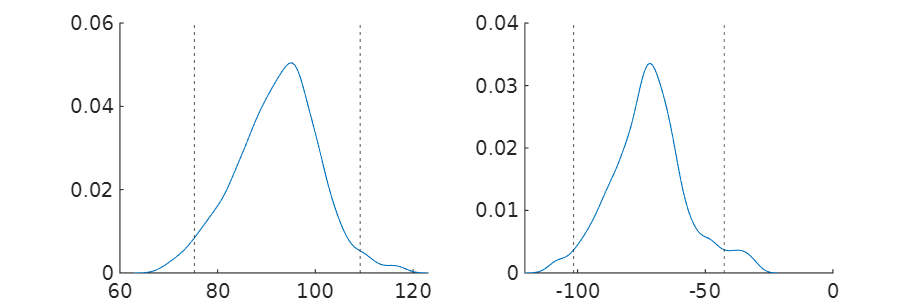


subplot(1, 2, 2); hold on;
ksdensity(dir_r);
xline(dir_r_m + [-2 2]*dir_r_s, 'LineStyle', ':');


change_of_mind = zeros(length(stage), 1);

for i = 1:length(stage)
    if perf=="Wrong"
        switch port_chosen(i)
            case 1
                dir_bias = abs(speed_dir(i, :) - dir_r_m) < 2*dir_l_s;
            case 2
                dir_bias = abs(speed_dir(i, :) - dir_l_m) < 2*dir_r_s;
        end
    else
        switch port_correct(i)
            case 1
                dir_bias = abs(speed_dir(i, :) - dir_r_m) < 2*dir_l_s;
            case 2
                dir_bias = abs(speed_dir(i, :) - dir_l_m) < 2*dir_r_s;
        end
    end
    len_bias = find(diff([0 dir_bias 0])==-1) - find(diff([0 dir_bias 0])==1);
    if any(len_bias >= 5)
        change_of_mind(i) = 1;
        if perf=="Wrong"
            port_plan(i) = 3 - port_chosen(i);
        else
            port_plan(i) = 3 - port_correct(i);
        end
    end
end

for i = 1:length(stage)
    if change_of_mind(i)==1
        continue
    end
    if perf=="Wrong"
        switch port_chosen(i)
            case 1
                dir_bias = abs(speed_dir(i, :) - dir_l_m) < 2*dir_l_s;
            case 2
                dir_bias = abs(speed_dir(i, :) - dir_r_m) < 2*dir_r_s;
        end
    else
        switch port_correct(i)
            case 1
                dir_bias = abs(speed_dir(i, :) - dir_l_m) < 2*dir_l_s;
            case 2
                dir_bias = abs(speed_dir(i, :) - dir_r_m) < 2*dir_r_s;
        end
    end
    len_bias = find(diff([0 dir_bias 0])==-1) - find(diff([0 dir_bias 0])==1);
    if ~any(len_bias >= 5)
        port_plan(i) = 0;
    end
end



perf_this = ["Correct", "Wrong", "Late"];

ratio_noplan_ctrl_left   = sum(port_plan==0 & port_correct==1 & label=="Control" & ismember(perf, perf_this) & hd>0.5) / sum(port_correct==1 & label=="Control" & ismember(perf, perf_this) & hd>0.5)

ratio_noplan_ctrl_left = 0.0453

ratio_noplan_chemo_left  = sum(port_plan==0 & port_correct==1 & label=="Chemo" & ismember(perf, perf_this) & hd>0.5) / sum(port_correct==1 & label=="Chemo" & ismember(perf, perf_this) & hd>0.5)

ratio_noplan_chemo_left = 0.0667

ratio_noplan_ctrl_right  = sum(port_plan==0 & port_correct==2 & label=="Control" & ismember(perf, perf_this) & hd>0.5) / sum(port_correct==2 & label=="Control" & ismember(perf, perf_this) & hd>0.5)

ratio_noplan_ctrl_right = 0.3103

ratio_noplan_chemo_right = sum(port_plan==0 & port_correct==2 & label=="Chemo" & ismember(perf, perf_this) & hd>0.5) / sum(port_correct==2 & label=="Chemo" & ismember(perf, perf_this) & hd>0.5)

ratio_noplan_chemo_right = 0.3432

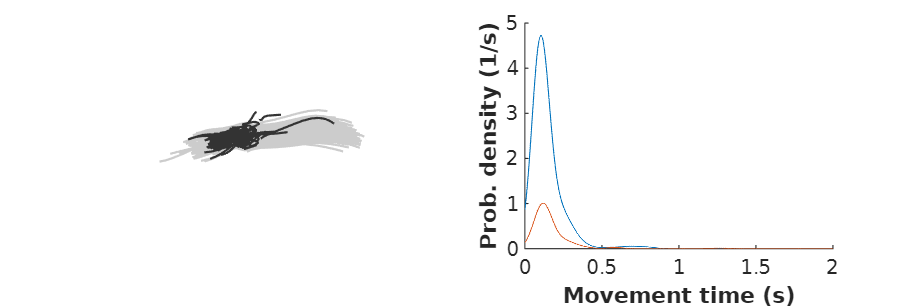


figure('Unit', 'Centimeters', 'Position', [5 5 15 5]);
subplot(1, 2, 1); hold on;
id_no_plan = find(port_plan==0 & ismember(perf, perf_this) & hd>0.5 & label=="Control");
id_planned = find(port_plan~=0 & change_of_mind==0 & ismember(perf, perf_this) & hd>0.5 & label=="Control");
for i = 1:length(id_planned)
    plot(pos_x_1(id_planned(i), :), pos_y_1(id_planned(i), :), 'Color', [.8 .8 .8 .6], 'LineWidth', 1);
end
for i = 1:length(id_no_plan)
    plot(pos_x_1(id_no_plan(i), :), pos_y_1(id_no_plan(i), :), 'Color', [.2 .2 .2 .6], 'LineWidth', 1);
end
set(gca, 'YDir', 'reverse', 'XLim', left_loc(1)*[-1.2 1.2], 'XColor', 'none', 'YColor', 'none'); axis equal

subplot(1, 2, 2); hold on;
if ~isempty(id_planned) && all(ismember(perf_this, ["Correct", "Wrong", "Late"]))
    [f, xi] = ksdensity(rt(id_planned), 0:0.001:2, 'Bandwidth', .05);
    plot(xi, f * (length(id_planned)/length([id_no_plan; id_planned])));
end
if ~isempty(id_no_plan) && all(ismember(perf_this, ["Correct", "Wrong", "Late"]))
    [f, xi] = ksdensity(rt(id_no_plan), 0:0.001:2, 'Bandwidth', .05);
    plot(xi, f * (length(id_no_plan)/length([id_no_plan; id_planned])));
end
xlabel("Movement time (s)", 'FontWeight', 'bold');
ylabel("Prob. density (1/s)", 'FontWeight', 'bold');

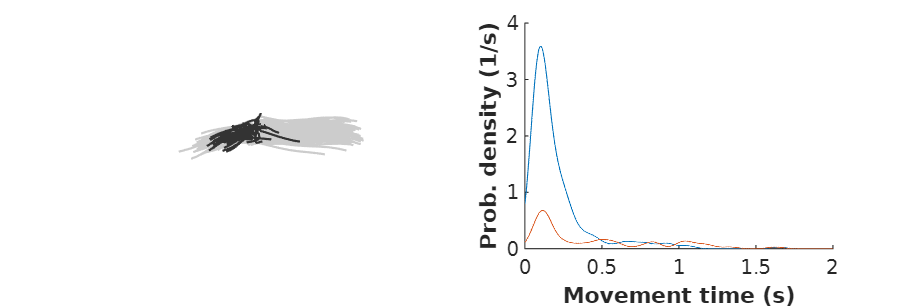


figure('Unit', 'Centimeters', 'Position', [5 5 15 5]);
subplot(1, 2, 1); hold on;
id_no_plan = find(port_plan==0 & ismember(perf, perf_this) & hd>0.5 & label=="Chemo");
id_planned = find(port_plan~=0 & change_of_mind==0 & ismember(perf, perf_this) & hd>0.5 & label=="Chemo");
for i = 1:length(id_planned)
    plot(pos_x_1(id_planned(i), :), pos_y_1(id_planned(i), :), 'Color', [.8 .8 .8 .6], 'LineWidth', 1);
end
for i = 1:length(id_no_plan)
    plot(pos_x_1(id_no_plan(i), :), pos_y_1(id_no_plan(i), :), 'Color', [.2 .2 .2 .6], 'LineWidth', 1);
end
set(gca, 'YDir', 'reverse', 'XLim', left_loc(1)*[-1.2 1.2], 'XColor', 'none', 'YColor', 'none'); axis equal

subplot(1, 2, 2); hold on;
if ~isempty(id_planned) && all(ismember(perf_this, ["Correct", "Wrong", "Late"]))
    [f, xi] = ksdensity(rt(id_planned), 0:0.001:2, 'Bandwidth', .05);
    plot(xi, f * (length(id_planned)/length([id_no_plan; id_planned])));
end
if ~isempty(id_no_plan) && all(ismember(perf_this, ["Correct", "Wrong", "Late"]))
    [f, xi] = ksdensity(rt(id_no_plan), 0:0.001:2, 'Bandwidth', .05);
    plot(xi, f * (length(id_no_plan)/length([id_no_plan; id_planned])));
end
xlabel("Movement time (s)", 'FontWeight', 'bold');
ylabel("Prob. density (1/s)", 'FontWeight', 'bold');

num_plan_ctrl  = sum(port_plan~=0 & label=="Control" & ismember(perf, perf_this) & hd>0.5)

num_plan_ctrl = 495

num_plan_chemo = sum(port_plan~=0 & label=="Chemo" & ismember(perf, perf_this) & hd>0.5)

num_plan_chemo = 279


ratio_plan_ctrl  = sum(port_plan~=0 & label=="Control" & ismember(perf, perf_this) & hd>0.5) / sum(label=="Control" & hd>0.5)

ratio_plan_ctrl = 0.7377

ratio_plan_chemo = sum(port_plan~=0 & label=="Chemo" & ismember(perf, perf_this) & hd>0.5) / sum(label=="Chemo" & hd>0.5)

ratio_plan_chemo = 0.6370

perf_this = "Correct";

ratio_change_ctrl_left   = sum(port_plan==2 & port_correct==1 & label=="Control" & ismember(perf, perf_this) & hd>0.5) / sum(port_correct==1 & label=="Control" & ismember(perf, perf_this) & hd>0.5)

ratio_change_ctrl_left = 0.0033

ratio_change_chemo_left  = sum(port_plan==2 & port_correct==1 & label=="Chemo" & ismember(perf, perf_this) & hd>0.5) / sum(port_correct==1 & label=="Chemo" & ismember(perf, perf_this) & hd>0.5)

ratio_change_chemo_left = 0

ratio_change_ctrl_right  = sum(port_plan==1 & port_correct==2 & label=="Control" & ismember(perf, perf_this) & hd>0.5) / sum(port_correct==2 & label=="Control" & ismember(perf, perf_this) & hd>0.5)

ratio_change_ctrl_right = 0.1010

ratio_change_chemo_right = sum(port_plan==1 & port_correct==2 & label=="Chemo" & ismember(perf, perf_this) & hd>0.5) / sum(port_correct==2 & label=="Chemo" & ismember(perf, perf_this) & hd>0.5)

ratio_change_chemo_right = 0.1278

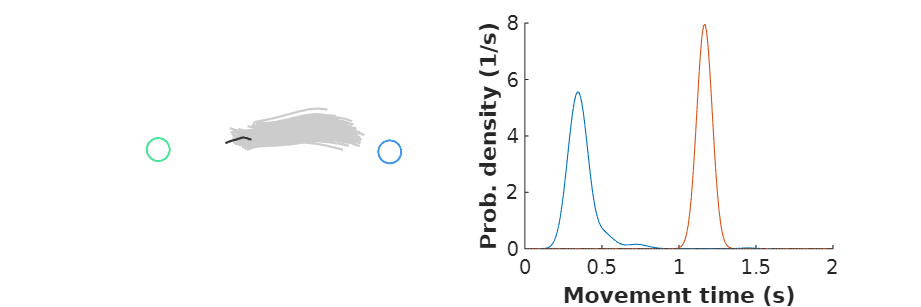


id_change = find(change_of_mind==1 & port_correct==1 & label=="Control" & ismember(perf, perf_this) & hd>0.5);
id_no_change = find(port_plan==1 & port_correct==1 & label=="Control" & ismember(perf, perf_this) & hd>0.5);
figure('Unit', 'Centimeters', 'Position', [5 5 15 5]);
subplot(1, 2, 1); hold on;
viscircles(right_loc, 30, 'Color', GPSColor.PortR, 'LineWidth', 1);
viscircles(left_loc, 30, 'Color', GPSColor.PortL, 'LineWidth', 1);
for i = 1:length(id_no_change)
    plot(pos_x_1(id_no_change(i), :), pos_y_1(id_no_change(i), :), 'Color', [.8 .8 .8 .6], 'LineWidth', 1);
end
for i = 1:length(id_change)
    plot(pos_x_1(id_change(i), :), pos_y_1(id_change(i), :), 'Color', [.2 .2 .2 .6], 'LineWidth', 1);
end
set(gca, 'YDir', 'reverse', 'XLim', left_loc(1)*[-1.2 1.2], 'XColor', 'none', 'YColor', 'none'); axis equal

subplot(1, 2, 2); hold on;
if ~isempty(id_no_change) && all(ismember(perf_this, ["Correct", "Wrong"]))
    ksdensity(mt(id_no_change), 0:0.01:2, 'Bandwidth', .05);
end
if ~isempty(id_change) && all(ismember(perf_this, ["Correct", "Wrong"]))
    ksdensity(mt(id_change), 0:0.01:2, 'Bandwidth', .05);
end
xlabel("Movement time (s)", 'FontWeight', 'bold');
ylabel("Prob. density (1/s)", 'FontWeight', 'bold');

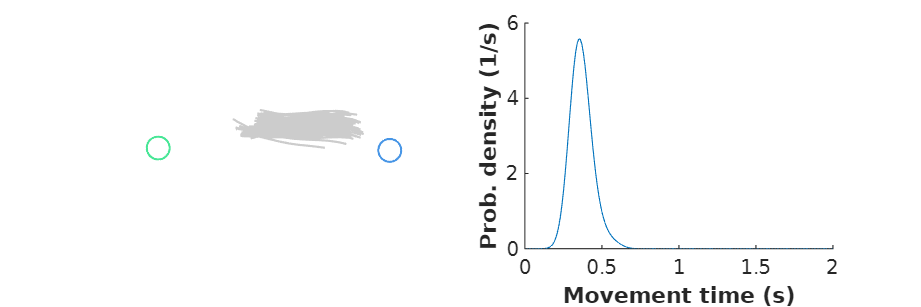


%
id_change = find(change_of_mind==1 & port_correct==1 & label=="Chemo" & ismember(perf, perf_this) & hd>0.5);
id_no_change = find(port_plan==1 & port_correct==1 & label=="Chemo" & ismember(perf, perf_this) & hd>0.5);
figure('Unit', 'Centimeters', 'Position', [5 5 15 5]);
subplot(1, 2, 1); hold on;
viscircles(right_loc, 30, 'Color', GPSColor.PortR, 'LineWidth', 1);
viscircles(left_loc, 30, 'Color', GPSColor.PortL, 'LineWidth', 1);
for i = 1:length(id_no_change)
    plot(pos_x_1(id_no_change(i), :), pos_y_1(id_no_change(i), :), 'Color', [.8 .8 .8 .6], 'LineWidth', 1);
end
for i = 1:length(id_change)
    plot(pos_x_1(id_change(i), :), pos_y_1(id_change(i), :), 'Color', [.2 .2 .2 .6], 'LineWidth', 1);
end
set(gca, 'YDir', 'reverse', 'XLim', left_loc(1)*[-1.2 1.2], 'XColor', 'none', 'YColor', 'none'); axis equal

subplot(1, 2, 2); hold on;
if ~isempty(id_no_change) && all(ismember(perf_this, ["Correct", "Wrong"]))
    ksdensity(mt(id_no_change), 0:0.01:2, 'Bandwidth', .05);
end
if ~isempty(id_change) && all(ismember(perf_this, ["Correct", "Wrong"]))
    ksdensity(mt(id_change), 0:0.01:2, 'Bandwidth', .05);
end
xlabel("Movement time (s)", 'FontWeight', 'bold');
ylabel("Prob. density (1/s)", 'FontWeight', 'bold');

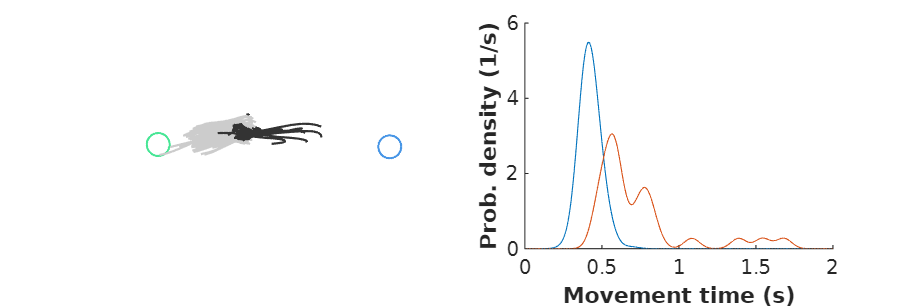


%
id_change = find(change_of_mind==1 & port_correct==2 & label=="Control" & ismember(perf, perf_this) & hd>0.5);
id_no_change = find(port_plan==2 & port_correct==2 & label=="Control" & ismember(perf, perf_this) & hd>0.5);
figure('Unit', 'Centimeters', 'Position', [5 5 15 5]);
subplot(1, 2, 1); hold on;
viscircles(right_loc, 30, 'Color', GPSColor.PortR, 'LineWidth', 1);
viscircles(left_loc, 30, 'Color', GPSColor.PortL, 'LineWidth', 1);
for i = 1:length(id_no_change)
    plot(pos_x_1(id_no_change(i), :), pos_y_1(id_no_change(i), :), 'Color', [.8 .8 .8 .6], 'LineWidth', 1);
end
for i = 1:length(id_change)
    plot(pos_x_1(id_change(i), :), pos_y_1(id_change(i), :), 'Color', [.2 .2 .2 .6], 'LineWidth', 1);
end 
set(gca, 'YDir', 'reverse', 'XLim', left_loc(1)*[-1.2 1.2], 'XColor', 'none', 'YColor', 'none'); axis equal

subplot(1, 2, 2); hold on;
if ~isempty(id_no_change) && all(ismember(perf_this, ["Correct", "Wrong"]))
    ksdensity(mt(id_no_change), 0:0.01:2, 'Bandwidth', .05);
end
if ~isempty(id_change) && all(ismember(perf_this, ["Correct", "Wrong"]))
    ksdensity(mt(id_change), 0:0.01:2, 'Bandwidth', .05);
end
xlabel("Movement time (s)", 'FontWeight', 'bold');
ylabel("Prob. density (1/s)", 'FontWeight', 'bold');

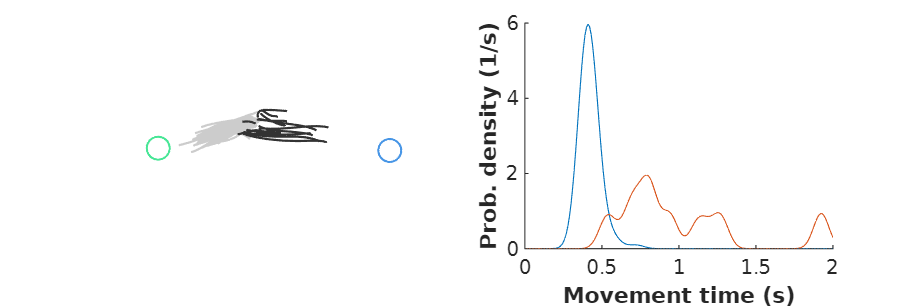


%
id_change = find(change_of_mind==1 & port_correct==2 & label=="Chemo" & ismember(perf, perf_this) & hd>0.5);
id_no_change = find(port_plan==2 & port_correct==2 & label=="Chemo" & ismember(perf, perf_this) & hd>0.5);
figure('Unit', 'Centimeters', 'Position', [5 5 15 5]);
subplot(1, 2, 1); hold on;
viscircles(right_loc, 30, 'Color', GPSColor.PortR, 'LineWidth', 1);
viscircles(left_loc, 30, 'Color', GPSColor.PortL, 'LineWidth', 1);
for i = 1:length(id_no_change)
    plot(pos_x_1(id_no_change(i), :), pos_y_1(id_no_change(i), :), 'Color', [.8 .8 .8 .6], 'LineWidth', 1);
end
for i = 1:length(id_change)
    l = plot(pos_x_1(id_change(i), :), pos_y_1(id_change(i), :), 'Color', [.2 .2 .2 .6], 'LineWidth', 1);
end
set(gca, 'YDir', 'reverse', 'XLim', left_loc(1)*[-1.2 1.2], 'XColor', 'none', 'YColor', 'none'); axis equal

subplot(1, 2, 2); hold on;
if ~isempty(id_no_change) && all(ismember(perf_this, ["Correct", "Wrong"]))
    ksdensity(mt(id_no_change), 0:0.01:2, 'Bandwidth', .05);
end
if ~isempty(id_change) && all(ismember(perf_this, ["Correct", "Wrong"]))
    ksdensity(mt(id_change), 0:0.01:2, 'Bandwidth', .05);
end
xlabel("Movement time (s)", 'FontWeight', 'bold');
ylabel("Prob. density (1/s)", 'FontWeight', 'bold');